# Solution: *Human Activity Recognition* exercise

## 0. Load data

Load the data in `HAData.mat`.

load HAData

This file contains a table, `data`, with 43 columns, containing sensor measurement data for experimental participants performing 6 different activities. The last column, `Activity`, contains a label for the activity being performed. **Note that the data is already normalized.**

## 1. Partition data

Partition the data into 70% training and 30% validation sets. 

rng(1234)
part = cvpartition(data.Activity,'HoldOut',0.3)

part = 홀드아웃 교차 검증 분할
   NumObservations: 5250
       NumTestSets: 1
         TrainSize: 3675
          TestSize: 1575

tridx = training(part)

tridx = 5250×1 logical 배열
   0
   1
   0
   0
   1
   1
   0
   1
   1
   1


tData = data(tridx,:)

tData = 3675×43 table
    AccMeanX     AccMeanY     AccMeanZ     AccStdX      AccStdY     AccStdZ     AccEnergyX    AccEnergyY    AccEnergyZ    GravAccMeanX    GravAccMeanY    GravAccMeanZ    GravAccStdX    GravAccStdY    GravAccStdZ    GravAccEnergyX    GravAccEnergyY    GravAccEnergyZ    AccJerkMeanX    AccJerkMeanY    AccJerkMeanZ    AccJerkStdX    AccJerkStdY    AccJerkStdZ    AccJerkEnergyX    AccJerkEnergyY    AccJerkEnergyZ    GyroMeanX     GyroMeanY    GyroMeanZ    GyroStdX     GyroStdY      GyroStdZ    GyroEnergyX    GyroEnergyY    GyroEnergyZ    GyroJerkMeanX    GyroJerkMeanY    GyroJerkMeanZ    GyroJerkStdX    GyroJerkStdY    GyroJerkStdZ    Activity
    ________    __________    _________    ________    _________    ________    __________    __________    __________    ____________    ____________    ____________    ___________    ___________    ___________    ______________    ______________    ______________    ____________    ____________    ____________    ___________  

vData = data(~tridx,:)

vData = 1575×43 table
    AccMeanX     AccMeanY     AccMeanZ     AccStdX      AccStdY      AccStdZ     AccEnergyX    AccEnergyY    AccEnergyZ    GravAccMeanX    GravAccMeanY    GravAccMeanZ    GravAccStdX    GravAccStdY    GravAccStdZ    GravAccEnergyX    GravAccEnergyY    GravAccEnergyZ    AccJerkMeanX    AccJerkMeanY    AccJerkMeanZ    AccJerkStdX    AccJerkStdY    AccJerkStdZ    AccJerkEnergyX    AccJerkEnergyY    AccJerkEnergyZ    GyroMeanX     GyroMeanY    GyroMeanZ    GyroStdX    GyroStdY     GyroStdZ    GyroEnergyX    GyroEnergyY    GyroEnergyZ    GyroJerkMeanX    GyroJerkMeanY    GyroJerkMeanZ    GyroJerkStdX    GyroJerkStdY    GyroJerkStdZ    Activity
    ________    __________    _________    ________    __________    ________    __________    __________    __________    ____________    ____________    ____________    ___________    ___________    ___________    ______________    ______________    ______________    ____________    ____________    ____________    ___________  

## 2. k-Nearest Neighbor, Cross-Validation, Hyperparameter Optimization

### 2.1. Fit a k-NN model and predict

Fit a kNN model to the training data with 5 number of neighbors and evaluate the classification using `resubLoss` and `loss.`

rng(1234)
mdlKNN = fitcknn(tData,'Activity','NumNeighbors',5); % Your code here
errKNN_train = resubLoss(mdlKNN)

errKNN_train = 0.0269

errKNN_test = loss(mdlKNN,vData)

errKNN_test = 0.0471

Predict the activity using the validation data and evaluate the classification using a `confusionchart.`

HDpred = predict(mdlKNN,vData)

HDpred = 1575×1 categorical 배열
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     Walking 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 
     UpStairs 


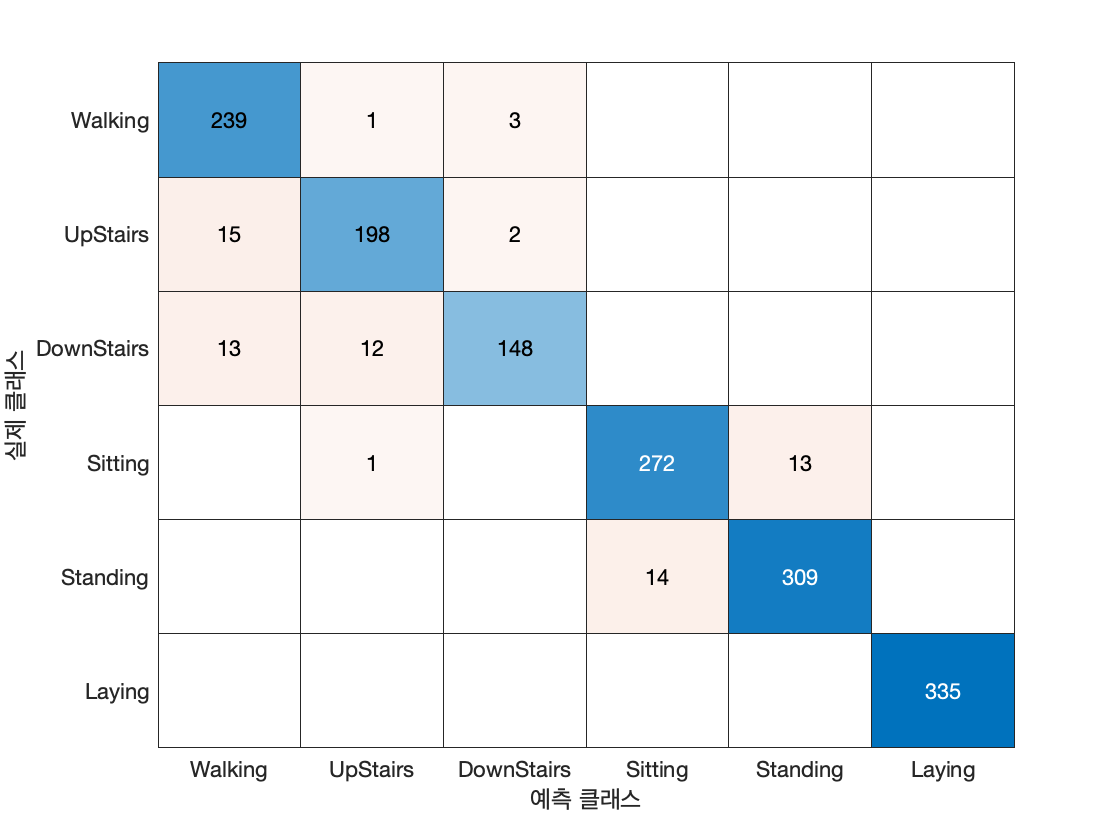

HDtrue = vData.Activity;
figure
confusionchart(HDtrue,HDpred)

### 2.2. Improve the k-NN model

#### As shown in 2.1., a kNN model already provided a good prediction result. Let's improve the model using cross-validation and hyperparameter optimization.

Create a 10-fold cross-validation partition.

rng(1234)
part2 = cvpartition(data.Activity,'KFold',10);
mdlknn_kfold = fitcknn(data,'Activity','CVPartition',part2) % 전체 데이터셋을 통으로 넣는다. 

mdlknn_kfold =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {1×42 cell}
           ResponseName: 'Activity'
        NumObservations: 5250
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [Walking    UpStairs    DownStairs    Sitting    Standing    Laying]
         ScoreTransform: 'none'


  Properties, Methods


errKNN_kfold = kfoldLoss(mdlknn_kfold)

errKNN_kfold = 0.0314

Fit a kNN model to the training data using hyperparameter optimization and k-fold cross validation.

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.096599 |     0.31542 |    0.096599 |    0.096599 |           28 |  correlation |


|    2 | Accept |     0.54776 |      0.7906 |    0.096599 |     0.11454 |         1830 |    cityblock |


|    3 | Accept |      0.4868 |      1.7089 |    0.096599 |     0.11369 |          362 |  mahalanobis |


|    4 | Accept |     0.84463 |     0.36762 |    0.096599 |     0.14337 |            5 |      jaccard |


|    5 | Accept |     0.10014 |     0.25167 |    0.096599 |    0.098396 |           37 |  correlation |


|    6 | Accept |     0.11728 |     0.26234 |    0.096599 |    0.098387 |           63 |       cosine |


|    7 | Accept |     0.11293 |     0.23652 |    0.096599 |    0.098383 |           63 |    euclidean |


|    8 | Accept |     0.17633 |     0.41511 |    0.096599 |    0.098381 |           55 |    chebychev |


|    9 | Best   |    0.052789 |     0.73259 |    0.052789 |    0.052816 |            1 |     spearman |


|   10 | Accept |      0.5815 |     0.89238 |    0.052789 |     0.05282 |         1838 |   seuclidean |


|   11 | Accept |     0.84626 |     0.38535 |    0.052789 |    0.052825 |           44 |      hamming |


|   12 | Best   |    0.044898 |     0.25907 |    0.044898 |    0.044931 |            1 |    minkowski |


|   13 | Accept |    0.044898 |     0.26002 |    0.044898 |    0.044914 |            1 |    minkowski |


|   14 | Accept |    0.044898 |      0.2543 |    0.044898 |    0.044909 |            1 |    minkowski |


|   15 | Accept |    0.044898 |     0.27812 |    0.044898 |    0.044906 |            1 |    minkowski |


|   16 | Accept |     0.51374 |     0.92408 |    0.044898 |     0.04491 |         1834 |    minkowski |


|   17 | Accept |     0.12354 |      0.6021 |    0.044898 |    0.044913 |          114 |     spearman |


|   18 | Accept |    0.044898 |     0.23718 |    0.044898 |    0.044916 |            1 |    euclidean |


|   19 | Best   |    0.044626 |     0.23101 |    0.044626 |    0.044918 |            1 |       cosine |


|   20 | Accept |    0.046259 |     0.22388 |    0.044626 |     0.04492 |            1 |  correlation |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |     0.10395 |     0.32592 |    0.044626 |    0.044921 |            1 |    chebychev |


|   22 | Accept |    0.044626 |     0.23059 |    0.044626 |     0.04492 |            1 |       cosine |


|   23 | Accept |    0.044898 |     0.39174 |    0.044626 |     0.04492 |            1 |    euclidean |


|   24 | Accept |    0.044626 |     0.25954 |    0.044626 |    0.044919 |            1 |       cosine |


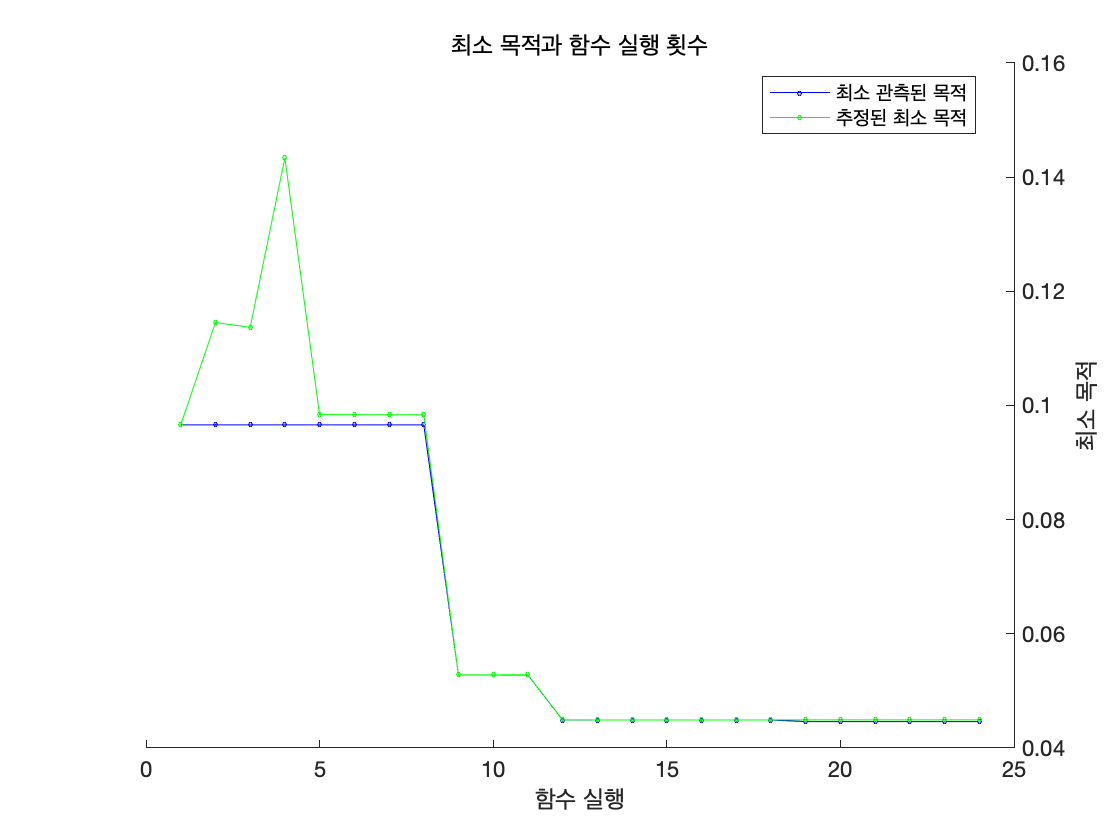

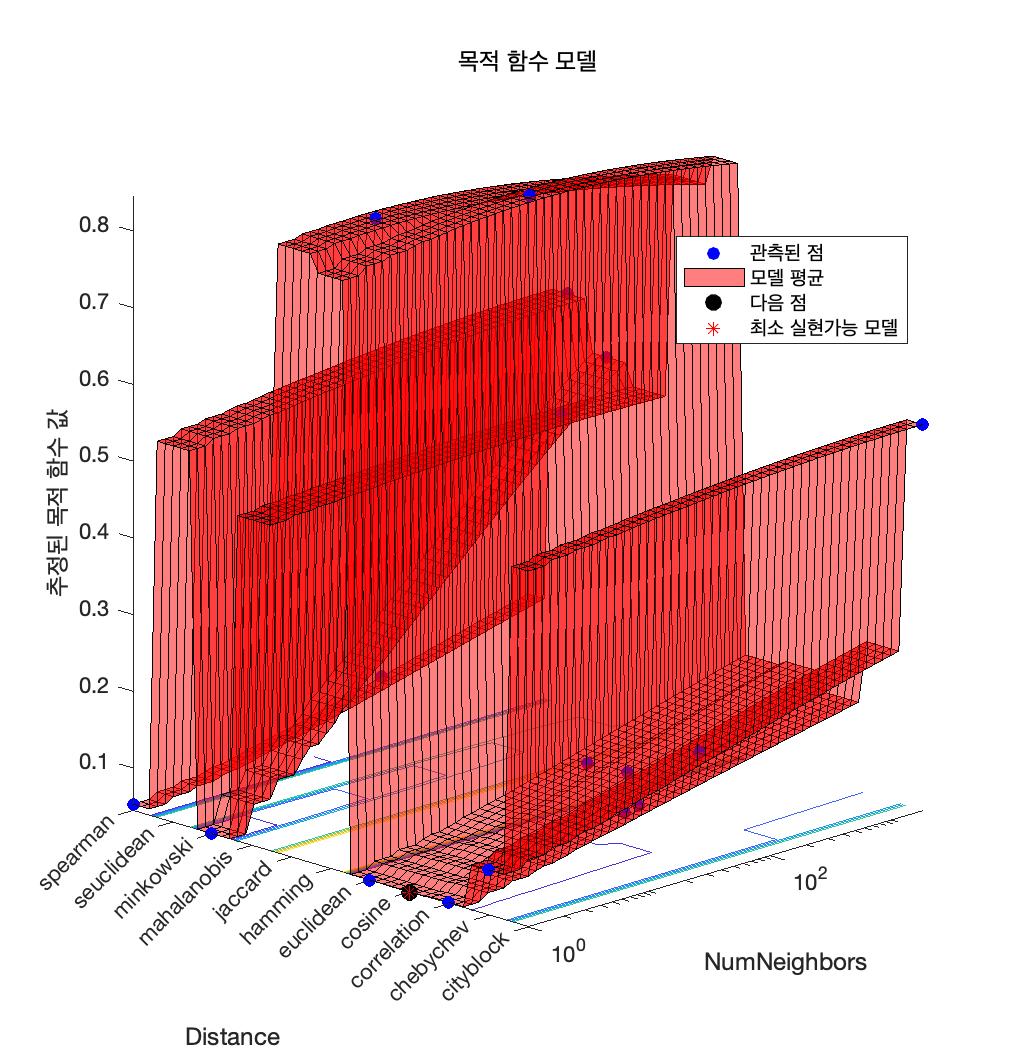

opts = struct('CVPartition',part,'MaxObjectiveEvaluation',20);% Your code here
mdlknn_HO = fitcknn(tData,'Activity','OptimizeHyperparameters','auto');

Evaluate the kNN model using `resubLoss` and `loss.`

resubLoss(mdlKNN_HO)
loss_knnHO = loss(mdlknn_HO,vData)

Display the improvement of the k-NN model.

disp(['kNN model improved by hyperparameter optimization: ', num2str(loss_knn), ' --> ', num2str(loss_knnHO)])

## 3. Naive Bayes, Sequential Feature Selection

### 3.1. Fit a Naive Bayes model and predict

Fit a NB model with 'kernel' distribution to the training data created in *1. Partition data,* and evaluate the classification using `resubLoss` and `loss.`

mdlNB = fitcnb(tdata,'HeartDisease',"DistributionNames","kernel");% Your code here
resubLoss(mdlNB)
loss_nb = loss(mdlNB,vdata) % Your code here

Predict the activity using the validation set and evaluate the classification using a `confusionchart.`

HDpred = predict(mdlNB,vData)
HDtrue = vData.Activity
figure
confusionchart(HDtrue,HDpred)

### 3.2. Improve the Naive Bayes model with Sequential Feature Selection

#### As shown in 3.1., a NB model does not provide as good prediction results as a kNN model. Let's improve the model using cross-validation and hyperparameter optimization.

Create a 10-fold cross-validation partition.

rng(1234)


Sequential feature selection on a Naive Bayes classifier. Which predictors are kept by sequential feature selection?

Fit a NB model with the selected predictors. Use 'kernel' distribution for a NB model with the training data created in 1. Partition data.



%mdlNB_reduced = % Your code here

Evaluate the classification using resubLoss and loss.

resubLoss(mdlNB_reduced)
loss_nbReduced = loss(mdlNB_reduced,vData)

### 3.3. Improve the Naive Bayes model with Cross-Validation and Hyperparameter Optimization

Create a 10-fold cross-validation partition.

rng(1234)
part2 = cvpartition(data.Activity,'KFold',10);
mdlNB_kfold = fitcnb(data,'Activity','CVPartition',part2) % 전체 데이터셋을 통으로 넣는다. 
errNB_kfold = kfoldLoss(mdlNB_kfold)

Fit a NB model to the training data using hyperparameter optimization and k-fold cross validation.

opts = struct('CVPartition',part,'MaxObjectiveEvaluation',20)% Your code here
%mdlNB_HO = % Your code here

Evaluate the NB model using `resubLoss` and `loss.`

resubLoss(mdlNB_HO)
loss_nbHO = fitcnb(tData,'Activity','OptimizeHyperparameters','auto');% Your code here

### 3.4. Improve the Naive Bayes model with Cross-Validation, Hyperparameter Optimization, and Sequential Feature Selection

Fit a NB model with the selected predictors from 3.2. Use hyperparameter optimization and k-fold cross validation.

%opts = % Your code here
%mdlNB_reduced_HO = % Your code here

Evaluate the NB model using `resubLoss` and `loss.`

resubLoss(mdlNB_reduced_HO)
%loss_nbReducedHO = % Your code here

Display the improvement of the Naive Bayes model.

mdlNames = {'NB kernel (all predictors)','NB kernel (reduced)', 'NB kernel (hyperOpti.)', 'NB kernel (reduced + hyperOpti.)'};
results = table(zeros(4,1),'RowNames',mdlNames,'VariableNames',{'Loss'});
results{1,1} = loss_nb; results{2,1} = loss_nbReduced; results{3,1} = loss_nbHO; results{4,1} = loss_nbReducedHO;
disp('Naive Bayes model improvement'); results

## 4. Ensemble Learning

Fit an ensemble to the training data created in *1. Partition data. *Use "Bag" as the ensemble creation method.

mdlEnsembleTree = fitcensemble(tData,Activity,'Method','Bag')% Your code here

Evaluate the ensemble model using `resubLoss` and `loss.`

resubLoss(mdlEnsembleTree)
loss_ensemble = loss(mdlEnsembleTree)% Your code here

Callback function: errorNB function returns the number of inaccurate predictions for `ytest` by a Naive Bayes classifier.

function error = errorNB(Xtrain,ytrain,Xtest,ytest)
mdlnb = fitcnb(Xtrain,ytrain,"DistributionNames","kernel");
ypred = predict(mdlnb,Xtest);
error = nnz(ypred ~= ytest);
end